# Figure S1F

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';
load([dataDir filesep 'A048_data.mat'],'S','settings','allIF');

conditions = settings.conditions;


framesPerHr = 60/12;
 frameDrugAdded =0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;



times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};
% 
for i = 1:length(S)
    S(i).frameDrugAdded = conditions{i,5};
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = ( S(i).frameDrugAdded - S(i).POI)/framesPerHr;
   S(i).drug_time = S(i).frameDrugAdded/framesPerHr;
end

 drug_time = frameDrugAdded/framesPerHr;

conds = [29];
figure('units','inches','position',[0 0 4 4]), hold on

POI_align = 3;
POI_cal = 6;
data_out = [];
frames_out = [];


for i=1:length(conds)
    data = S(conds(i));
    inds = ~isnan(S(conds(i)).POI(:,2)) & ~isnan(S(conds(i)).POI(:,3))&...
        S(conds(i)).POI_realtime(:,3) - S(conds(i)).POI_realtime(:,2)>= 0 ;
    event = data.POI(:,POI_cal);

    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

    y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of s relative to apc
    lost = lost/framesPerHr; % lost = last frame relative to apc
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);

  
[f,x] = ecdf(y(inds),'Censoring',censor(inds));

     hold on
    plot(x,f,'LineWidth',2,'LineStyle','-','color',[.2 .6 .9]);
  sum(inds)



   
     data = S(conds(i));
      inds = ~isnan(S(conds(i)).POI(:,3))&   ~isnan(S(conds(i)).POI(:,2))&...
        S(conds(i)).POI_realtime(:,3)- S(conds(i)).POI_realtime(:,2) < 0 ;%& S(conds(i)).apcExpressGate;% &...;% & S(conds(i)).POI_realtime(:,3)  >= timeGate(2)  | isnan(S(conds(i)).POI(:,3))&...
 
        event = data.POI(:,POI_cal);

    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

    y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of s relative to apc
    lost = lost/framesPerHr; % lost = last frame relative to apc
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);

  
[f,x] = ecdf(y(inds),'Censoring',censor(inds));

     hold on
     plot(x,f,'LineWidth',2,'LineStyle','--','Color',[.8 .1 .2]);
  sum(inds)


    


 legend ('APC inactivation before S phase','APC inactivation after S phase','Location','northwest','box','off','fontsize',16)


    
  
end

ans = 429

ans = 1538

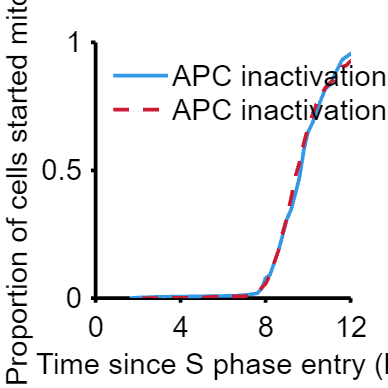

% legend(conditions(conds,1));
set(gca,'fontsize',16,'linewidth',2)
xlim([0 12]); 
xticks([0:4:12])
ylim([0 1]);
xlabel('Time since S phase entry (h)')
ylabel('Proportion of cells started mitosis')
axis square

% print_pdf(['fig_S1F.pdf'])